format short, format compact
close all force
clear, clc

%% data description
% in this data set, and animal is running on a wheel. There are two pistons
% near the face. When one piston shoots out, every time the animals whisks,
% the C1 whisker touches the piston. When the second piston is extended,
% the D1 whisker touches the piston during whisking. Only one piston is
% extended at a time.
load('20231011_Mouse3_ArduinoData.mat')
whos

  Name      Size               Bytes  Class     Attributes

  data      1x1             10049510  struct              



fieldnames(data)

ans = 10×1 cell array
    {'date'           }
    {'phase'          }
    {'dist'           }
    {'lick'           }
    {'valve'          }
    {'pistonGO'       }
    {'pistonNOGO'     }
    {'GOperformance'  }
    {'NOGOperformance'}
    {'t'              }

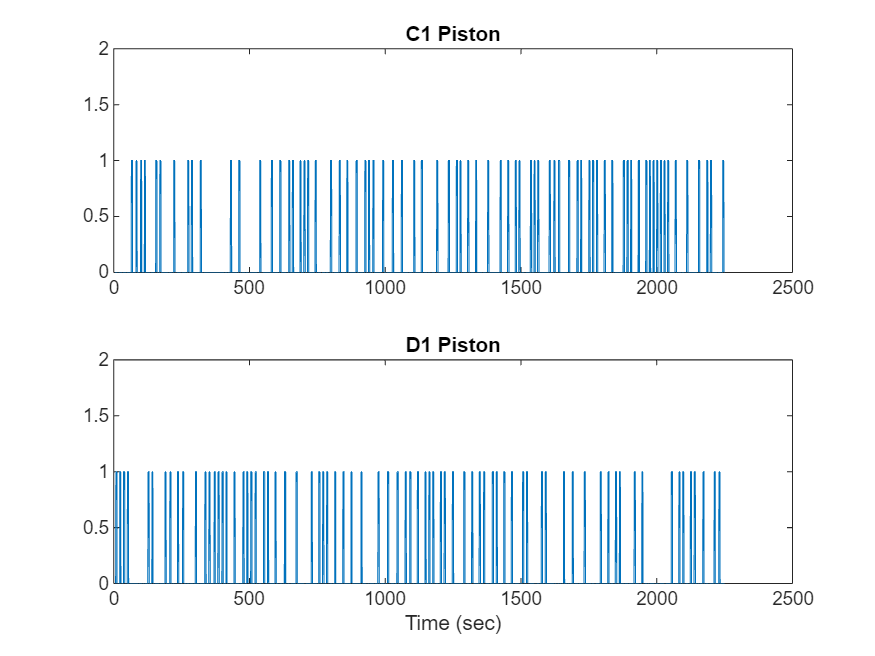

%plot when the pistons are extended during the full experiment. When the
%piston has a value of 1 it is extended. If you zoom in you can see they
%are never extended at the same time
figure
subplot(211)
plot(data.t,data.pistonGO)
title('C1 Piston')
subplot(212)
plot(data.t,data.pistonNOGO)
title('D1 Piston')
linkaxes
ylim([0 2])
xlabel('Time (sec)')

%% calcium data
%load calcium data set
%clear
load('2P.mat')
whos

  Name                    Size                   Bytes  Class     Attributes

  A                  262144x912                1427352  double    sparse    
  AverageImage          512x512                2097152  double              
  C                     512x512                1048576  single              
  DeltaFoverF           575x44065            202699000  double              
  Noise_Power           575x44065            202699000  double              
  ROI                   575x1                  1549600  cell                
  ROIcentroid           575x1                     4600  double              
  ans                    10x1                     1178  cell                
  badComponents         189x1                     1512  double              
  dDeltaFoverF          575x44065            202699000  double              
  data                    1x1                 10049510  struct              
  files                   1x31                      62  char               

fieldnames(ops)

ans = 126×1 cell array
    {'d1'                }
    {'d2'                }
    {'d3'                }
    {'ssub'              }
    {'tsub'              }
    {'init_method'       }
    {'rem_prct'          }
    {'noise_norm'        }
    {'noise_norm_prctile'}
    {'min_corr'          }
    {'gSig'              }
    {'gSiz'              }
    {'nb'                }
    {'nIter'             }
    {'med_app'           }
    {'save_memory'       }
    {'chunkSiz'          }
    {'windowSiz'         }
    {'rolling_sum'       }
    {'rolling_length'    }
    {'snmf_max_iter'     }
    {'err_thr'           }
    {'eta'               }
    {'beta'              }
    {'max_iter_hals_in'  }
    {'bSiz'              }
    {'maxIter'           }
    {'noise_range'       }
    {'noise_method'      }
    {'max_timesteps'     }

%load data that gives us info about which piston is extended
%clear
load('trialData.mat')
whos

  Name                    Size                   Bytes  Class     Attributes

  A                  262144x912                1427352  double    sparse    
  AverageImage          512x512                2097152  double              
  C                     512x512                1048576  single              
  DeltaFoverF           575x44065            202699000  double              
  Noise_Power           575x44065            202699000  double              
  ROI                   575x1                  1549600  cell                
  ROIcentroid           575x1                     4600  double              
  ans                   126x1                    15358  cell                
  badComponents         189x1                     1512  double              
  dDeltaFoverF          575x44065            202699000  double              
  data                    1x1                 10049510  struct              
  files                   1x31                      62  char               

fieldnames(trial)

ans = 3×1 cell array
    {'whiskerNum'}
    {'length'    }
    {'numFrames' }

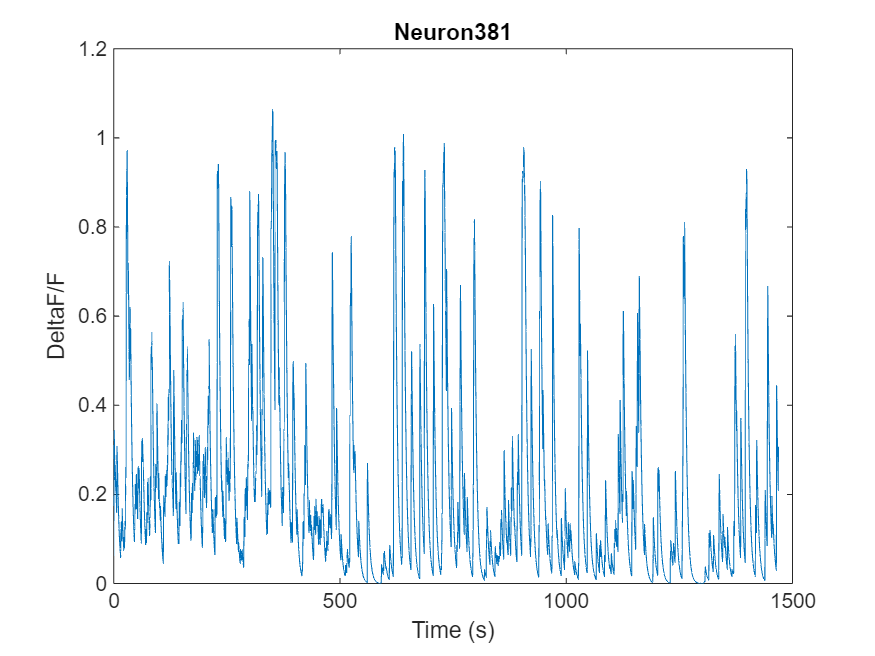

%remove all the false positive neurons from the data (painfully curated
%the data to decide which neurons are "fake")
DeltaFoverF(badComponents,:) = [];
%(note you only want to run this ^^^ one time after loading the data. if you do
%it again it will throw an error)

%you can see DeltaFoverF has 389 rows and 44065 columns. This means 389
%neurons and 44065 data points for each neuron. Each data point
%corresponds to a camera frame

%the imaging rate is 30 fps
Fr = 30;
%so the total length of the data set in seconds is 44065/30 = 1468 seconds

%% Plots the full calcium data for neuron n

%choose a random neuron
n = 381;
data = DeltaFoverF(n,:);
%use the imaging rate to get the x-axis in units of seconds. 
% i.e. frame 1 = 0.033 s, frame 2 = 0.066 s, frame 3 - 0.099 s
t = (1:length(data))./Fr;%time in seconds

%plot
figure
plot(t,data)
xlabel('Time (s)')
ylabel('DeltaF/F')
title(['Neuron' num2str(n)])

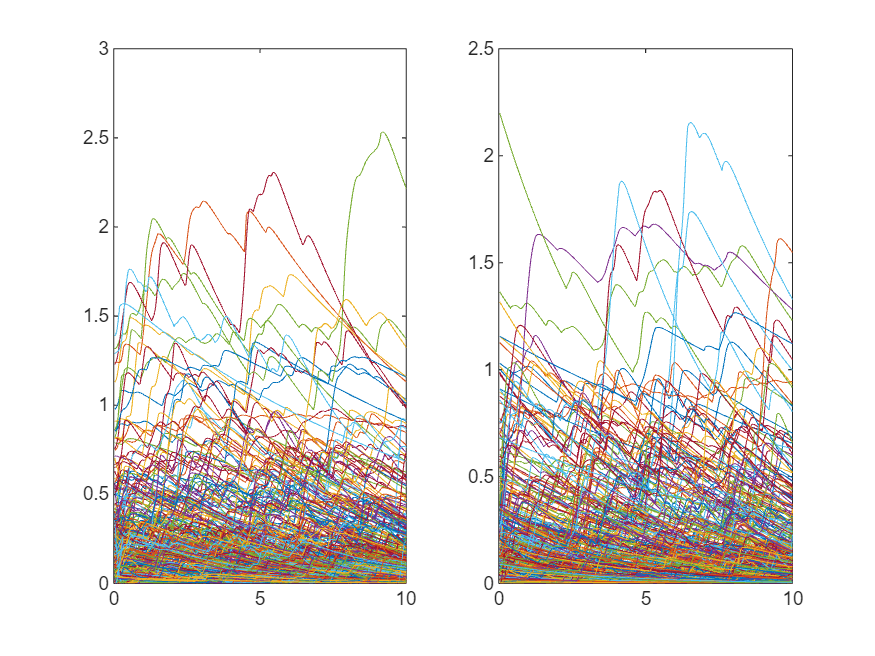


%% plot only trial 1 and trial 2 for all neurons
%the variable trial.NumFrames gives info about how long each trial lasted.
%They are all about 300 frames (i.e. 10 seconds) but vary a little from
%trial to trial. trial 5, for example is 9.3 seconds, so: trial.numFrames(5) = 279, not 300.
% More examples:
% trial.numFrames(1) = 300. So in the calcium data, each index from 1-300 is
% for trial 1
% trial.numFrames(2) = 300. So in the calcium data, each index from 301-600 is
% for trial 2

framesForTrial1 = 1:trial.numFrames(1);
framesForTrial2 = (trial.numFrames(1)+1):(trial.numFrames(1)+trial.numFrames(2));

%again, we want the x-axis in terms of time
time1 = (1:length(framesForTrial1))./Fr;
time2 = (1:length(framesForTrial2))./Fr;

figure
%plot response of all neurons for trial 1
subplot(121)
plot(time1,DeltaFoverF(:,framesForTrial1)')
subplot(122)
plot(time2,DeltaFoverF(:,framesForTrial2)')

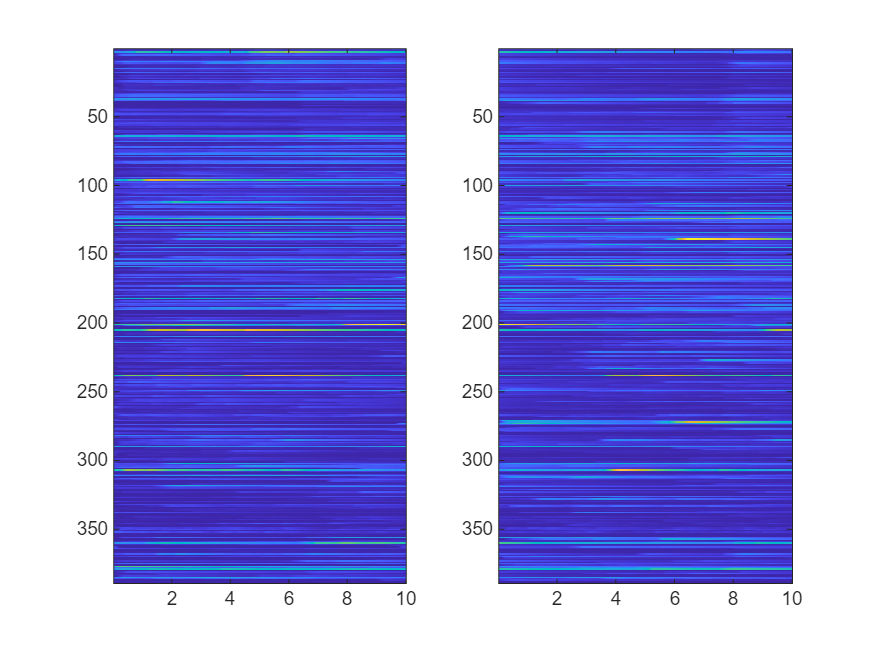

%you can see it's kind of a mess, because of the nearly 400 neurons, only a
%few are strongly responding to the whisker stimuli

%same data but plotted as a heatmap
figure
subplot(121)
imagesc(time1,[],DeltaFoverF(:,framesForTrial1))
subplot(122)
imagesc(time2,[],DeltaFoverF(:,framesForTrial2))

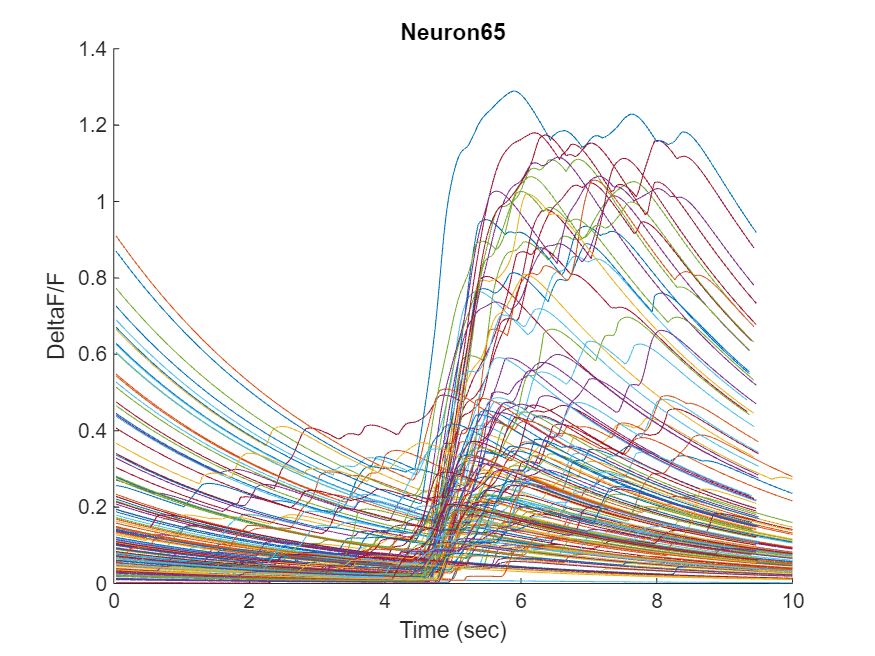


%the piston pops out at t = 4 seconds after the trial begins

%% get frames for every trial
% the "framesForTrialX" method above is too slow. This bit of code iterates
% quickly so you can get the frames for all trials
trialFrames{1} = 1:trial.numFrames(1);
for tt = 2:length(trial.numFrames)
    trialFrames{tt} = (trialFrames{tt-1}(end)+1):(trialFrames{tt-1}(end)+trial.numFrames(tt));
end

%% overlay calcium traces for all trials for neuron n
%choose a neuron
n = 65;
%full calcium trace for this neuron
calciumData = DeltaFoverF(n,:);
%plot all trials for this neuron
figure
hold on
for tt = 1:length(trial.numFrames)
    trialData = calciumData(trialFrames{tt});
    
    t = (1:length(trialData))./Fr;
    plot(t,trialData)
end
xlabel('Time (sec)')
ylabel('DeltaF/F')
title(['Neuron' num2str(n)])

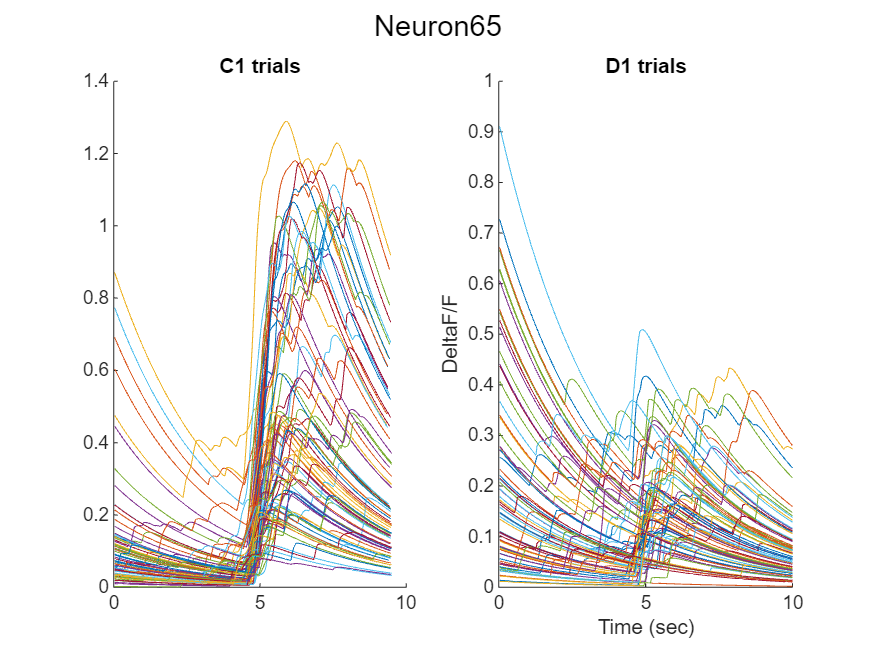


%you can see this neurons responds to whisker touch. Recall the piston
%shoots out at t = 4 seconds

%% The above example is for *all* trials. what about one piston vs another? 
%for each trial, the variable trial.whiskerNum gives us info about which
%whisker is being touched. If trial.whiskerNum = 2, then that trial was for
%the D1 whisker. if trial.whiskerNum = 1, then that trial was for the C1
%whisker. So:
%trial.whiskerNum(1) = 2, so that is a D1 trial
%trial.whiskerNum(5) = 1, so that is a C1 trial

%repeat the same plotting above, but plot the calcium data separately
%depending on whether the trial was a D1 or C1 whisker trial
%choose a neuron
n = 65;
%full calcium trace for this neuron
calciumData = DeltaFoverF(n,:);

figure
ax(1) = subplot(121);hold on;title('C1 trials')
ax(2) = subplot(122);hold on;title('D1 trials')
for tt = 1:length(trial.numFrames)
    trialData = calciumData(trialFrames{tt});
    t = (1:length(trialData))./Fr;

    if(trial.whiskerNum(tt) == 1)%if this is a C1 trial
        %plot on ax(1)
        plot(ax(1),t,trialData)
    elseif(trial.whiskerNum(tt) == 2)%if this is a D1 trial
        %plot on ax(2)
        plot(ax(2),t,trialData)
    end
end
xlabel('Time (sec)')
ylabel('DeltaF/F')
sgtitle(['Neuron' num2str(n)])


%you can see this neuron responds to touch of both whiskers, but is more
%selective to C1
%% some good things to try
% -plot the full data trace for some more neurons
% -Find more neurons that are strongly responsive to touch
% -Find ~10 neurons that strongly respond to touch. Then plot the full
% calcium trace for 5 consecutive trials
% -Find more neurons that are selective to C1 or D1